clc;
clear;
close all;

## 添加路径

addpath('functions\')
addpath('mainASM\')
addpath('class\')
addpath('drawShape\')
addpath('镜头\')

## 参数设置

# Gaussian Beam

lambda=647e-6;
beamSize=2;       %初始高斯光束腰斑直径
beamStd=beamSize/2.85;
beamAmp=1;
noise=0.5;
beam=GaussianBeam(beamAmp,beamStd,lambda);
color=wavelength2color(lambda*10^6, 'gammaVal', 2.2, 'maxIntensity', 1, 'colorSpace', 'rgb');
R=linspace(0,color(1),65535)';
G=linspace(0,color(2),65535)';
B=linspace(0,color(3),65535)';
mymap=[R G B];
colormap(mymap)

# MLA

rla1=-1.1;% 透镜1的曲率半径    
d = 0.15;% 透镜单元边长
t = 1.2;% 透镜厚度
N=40;% 微透镜单元采样点数
material={"F_SILICA"};
MLA1=Lens([rla1,inf],t,d,material,lambda);
MLA2=Lens([inf,-rla1],t,d,material,lambda);
num=floor(beamStd/d*5);            %数量
if num==0
    num=1;
end
area1 = num*d;           % 光场的面积
area2=12.9;
area3=12.8;
rate=(d/N);           %采样率（global）
area2=findClosestDivisible(area2,rate);

peak=0;
SD=0;
uniformity=0;
beams=GaussianBeam.defocused(beam,10,N*num,rate);%.*drawCircle(round(N*num)/2,0,0,round(area1/rate),round(area1/rate));
beamApt=drawCircle(round(size(beams,1)/2),0,0,size(beams,1),size(beams,2));
beams=beams.*beamApt;
I_sum=sum(abs(beams).^2,'all');

# Ex-MLA

rla_ex = -1.6;            % 透镜1的曲率半径
d_ex = 0.15;              % 透镜单元边长
t_ex=1;
material_ex={"F_SILICA"};
MLA3=Lens([rla_ex inf],t_ex,d_ex,material_ex,lambda);

aperture=drawCircle(23/2/rate,0,0,round(area3/rate),round(area3/rate));

distance1 = 1;   % 投影距离
distance2 = 70.169;   % 投影距离
distance3 = 75;
distance4 = 2.795;

# Fourier Lens

%{
rfl1 = -386.511;            % 傅里叶透镜的曲率半径（胶合透镜）
rfl2 = -132.37;
rfl3 = 185.841;
dfl = 40;              % 傅里叶透镜直径
tfl = [3,5];            % 傅里叶透镜厚度
material_fl={'ZF2','H-K9L'};
FL=Lens([rfl1,rfl2,rfl3],tfl,dfl,material_fl,lambda);
%}
Dfl = area2;              %采样区域
%file='Lens.txt';
%file='OLD2444-T2M(JCOPTIX-F=100胶合).txt';
file='OLD2440-T2M(JCOPTIX-F=74.9胶合).txt';
%file='OLD2430-T2M(JCOPTIX-F=30胶合).txt';
%{
f_str=strsplit(file,'F=');
ff_str=strsplit(f_str{2},'胶合');
f_FL=ff_str{1};
%}
FL=readLens(file,lambda);

# Diffuser

rpm=50000;%电机转速(圈每分钟)
rpus=rpm/60/1000/1000;
radius_diffuser=22;%散射片半径mm
velocity=2*pi*rpus*radius_diffuser;%线速度
deltat=1;%
T=1000;%积分时间（μs）
times=floor(T/deltat);
route=velocity*T;
if route>2*pi*radius_diffuser
    route=2*pi*radius_diffuser;
    T=route/velocity;
    times=floor(T/deltat);
end
diffuserAngle=0.5;   %散射片散射角度
diffuser=Diffuser(diffuserAngle,lambda);
phase=Diffuser.generateDiffuser(diffuser,rate,[round(route/rate)+size(beams,1),N*num]);

# Objective Lens

n_oil=1;
f_TL=200;
beta=100;
f_OBJ=f_TL/beta;
NA=1.49;
rate2=1/area3*lambda*f_TL;%管镜焦面采样率
area4=(rate2*area3/rate);%管镜焦面计算大小
rate3=1/area4*lambda*f_OBJ/n_oil;%样品面采样率
rP=f_OBJ*NA;
mask=drawCircle(rP/rate2,0,0,area2/rate,area2/rate);

## 生成透镜相位

%%生成匀光微透镜阵列厚度函数
Lens.lensArrayThickFcn(MLA1,N,num,'square');
Lens.lensArrayThickFcn(MLA2,N,num,'square');
%% 生成傅里叶透镜厚度函数
Lens.lensThickFcn(FL,Dfl,round(area2/rate));
%% 生成激发微透镜阵列厚度函数
lensArray.lensArrayThickFcn2(MLA3,d_ex/rate,area3/d_ex,'square',0,d_ex-0.001,0)


Lens.lensSingle(MLA1)
Lens.lensSingle(MLA2)
Lens.lensSingle(FL);
Lens.lensSingle(MLA3);


beams=single(beams);
N=single(N);
num= single(num);
Diffuser.diffuserSingle(diffuser)
rate= single(rate);
lambda= single(lambda);
distance2= single(distance2);
distance3= single(distance3);
distance4= single(distance4);
area1= single(area1);
area2= single(area2);
area3= single(area3);

if canUseGPU
    Lens.lensGPUArray(MLA1)
    Lens.lensGPUArray(MLA2)
    Lens.lensGPUArray(FL)
    Lens.lensGPUArray(MLA3);
    beams=gpuArray(beams);
    N= gpuArray(N);
    num= gpuArray(num);
    Diffuser.diffuserGPUArray(diffuser)
    rate= gpuArray(rate);
    lambda= gpuArray(lambda);
    distance2= gpuArray(distance2);
    distance3= gpuArray(distance3);
    distance4= gpuArray(distance4);
    area1= gpuArray(area1);
    area2= gpuArray(area2);
    area3= gpuArray(area3);
end
I=zeros(round(area3/rate));

## 光场变换

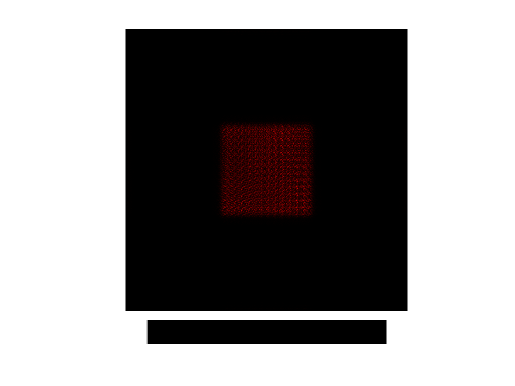

tic
for ii=1:times
    %叠加随机相位
    beamss=GaussianBeam.beamNoise(beams,0.05,0);
    %beamss=beamss.*beamApt;
    F = transform(beamss, area1, lambda, 20, [rate, rate]);
    
    index=round((velocity*(ii-1)*deltat)/rate+1);
    F=F.*phase(index:index+size(F,1)-1,:);
    %{
    if mod(ii,2)
        [phase1,phase2]=Diffuser.generateDiffuser(diffuser,rate,[N*num,N*num]);
        
        F=F.*phase1;
    else
        F=F.*phase2;
    end
    %}
    F = transform(F, area1, lambda, 20, [rate, rate]);
    afterLens=ASMinLens(F,MLA1,lambda,area1);
    F = transform(afterLens, area1, lambda, distance1, [rate, rate]);
    afterLens=ASMinLens(F,MLA2,lambda,area1);
    F = transform(afterLens, area2, lambda, distance2, [rate, rate]);
    afterLens = ASMinLens(F,FL,lambda,area2);
    F = transform(afterLens, area3, lambda, distance3, [rate, rate]);
    %afterLens = ASMinLens(F,MLA3,lambda,area3);
    %F = transform(afterLens, area3, lambda, distance4, [rate, rate]);
    %传播到样品面
    %F=F.*aperture;
    %F=FT2Dc(F);
    %F=mask.*F;
    %F=IFT2Dc(F);

    I_now=abs(F).^2;
    I = I+I_now;

    Inorm=imnorm(I);
    subplot(10,10,[1,90])
    imshow(uint16(Inorm*65536),mymap)
    
    Inorm=gather(Inorm);
    [u(ii),sigma(ii),N_per(ii)]=homoanalyse(Inorm);
    %每20个循环计算一次平均FWHM
    %{
    if mod(ii,20)==0
        [FWHM,~,peakmap,num,~,~]=spotAna(Inorm,0.5,d_ex,rate);
        disp(['平均FWHM=' num2str(FWHM*1e3) 'μm'])
        disp(['光斑数：' num2str(num)])
    end
    %}
    subplot(10,10,[91,100])
    progressBar([100,1000],ii/times)
    drawnow
    
end


figure
plot(u)
figure

%imwrite(double(Inorm),['微透镜匀光仿真/P' num2str(d*1000) 'T=' num2str(T) 'usFL' f_FL 'A=' num2str(area2) 'D=' num2str(diffuserAngle) '2.jpg'])